## Part 1


n = 100; %1mm^3 pixel sizes I believe if cube size is 10cm.
I = zeros(n,n,n); %creating 0 matrix of large sampling size

dx = 0.1; 
x = -5:dx:5-dx; %5-dx is needed to make vector size fit 100x100x100
y = x;
z = x;

[X, Y, Z] = meshgrid(x,y,z); %combines xyz vectors to make 3D matrix


distance = sqrt(X.^2 + Y.^2 +Z.^2); %assuming this creates a matrix describing the distance of each coordinate from the center 0
mask = distance<2.5; %mask takes every distance and gives a voxel value of 1 only to those within a 2.5cm radius of the center (creating our circle). 
I(mask) = 1; %applies the mask to our zeros matrix
I(50,50,50) %Proof that the voxels are labeled 1, correctly. 

ans = 1

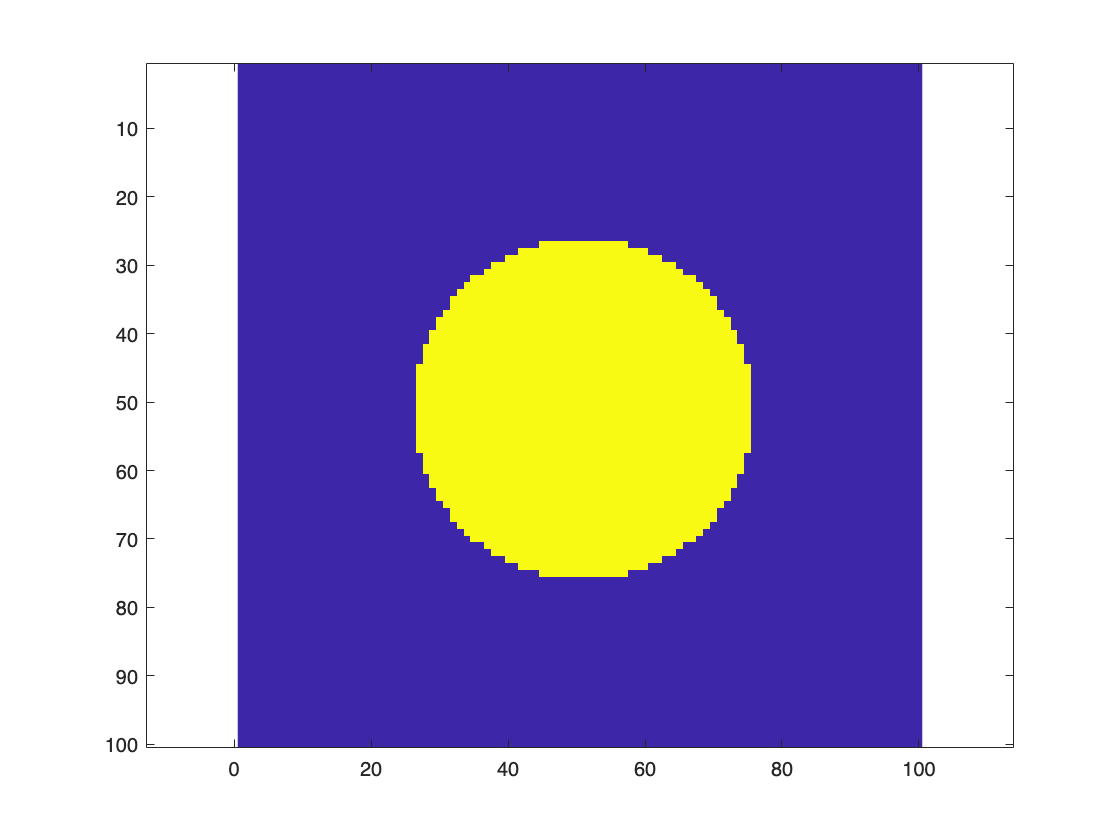


figure, imagesc(squeeze(I(:,:,50))), axis equal %visualizes the circle with z = 0cm. 

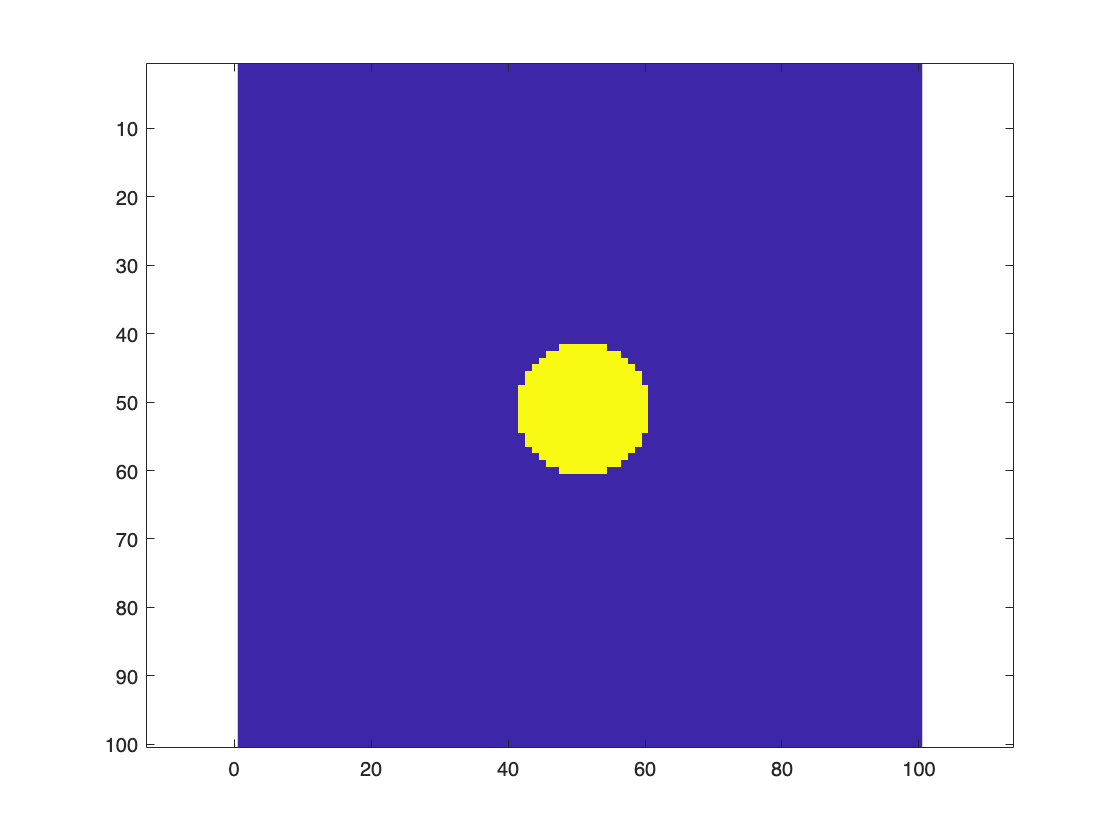

figure, imagesc(squeeze(I(:,:,(24+50)))), axis equal %visuazlizes the circle with z = 2.4cm; if 50 is the center adding 24 is adding 2.4


## Part 2

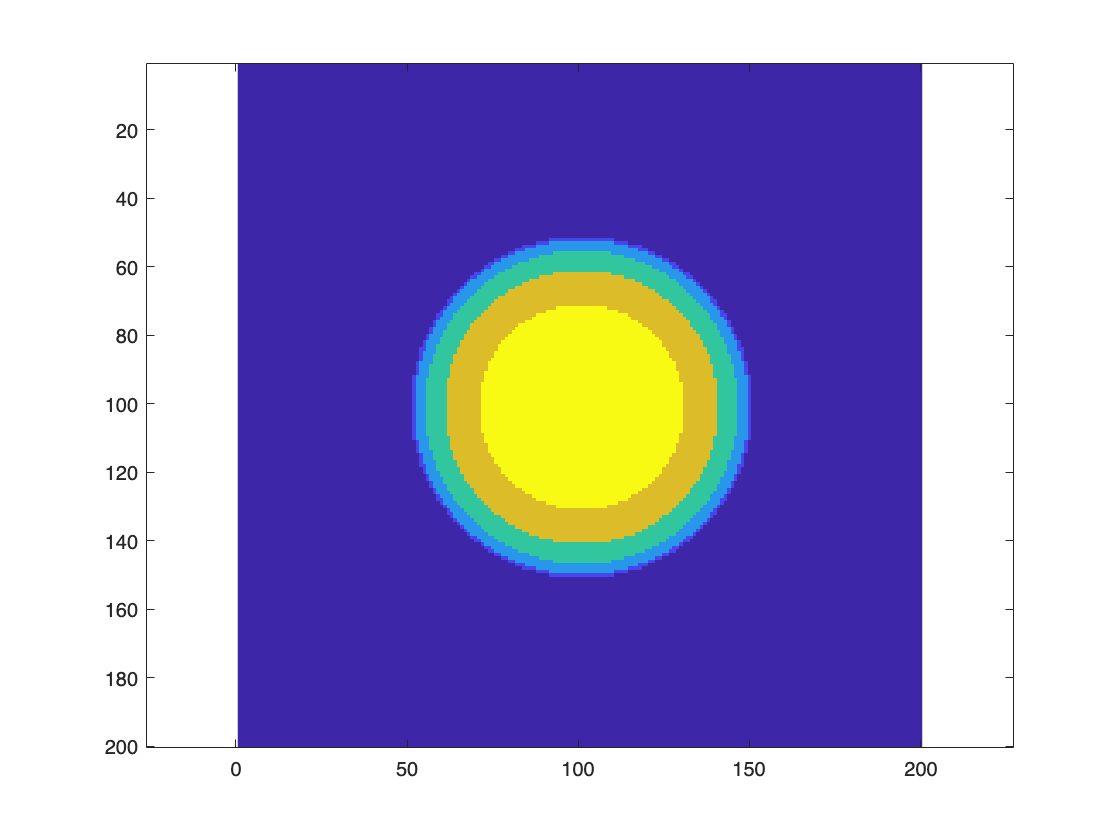

%Instead of last time, I'm going to use the zeros function with the size X
%after I use the meshgrid function. Which should make a compatable Image
%matrix instead of overthinking it (which I definitely am at this point). 


dx = 0.05; %0.5mm resolution we think
x = -5:dx:5-dx; 
y = x;
z = x;
[X, Y, Z] = meshgrid(x,y,z);

I = zeros(size(X));

distance = sqrt(X.^2 + Y.^2 +Z.^2); 
mask = distance<2.5; %circle creation again
I(mask) = 1;


%Simulating finite slice thickness:
%Plan is to index at each .5cm in the z direction, add each slice together
%and then divide by the total number of slices 20 (maybe 21) for the mean. 

slice_number = -5:.5:5; %gives me equal slice positions 
slice_int = zeros(size(I)); %creates matrix for the averaged slices

for i = 1:numel(slice_number) %loop to add each slice at the desired thickness
slice = slice_number(i); 

[~,J] = min(abs(z-slice));
%discovered I can make J an integer indicating the column number(1-200),
%which I can put into matrix I) by using ~ in the rows.

%subtracting z and slice will place a 0 in the column of the coordinate of
%the needed slice. min function takes the smallest element of the matrix as
%long as I use abs to make sure its non-negative. 

slice_z = I(:,:,J); %ran into error here, because I was putting a negative number and non-integers into I. added above function and explained to help get actual coordinates.
slice_int = slice_int + slice_z;
end
slice_int = slice_int / numel(slice_number); %adding this doesn't seem to make a change, something in the notes asks for a mean so I figured this wouuld be similar to a convolution or something close. 

%formulating integrated slices into image
figure, imagesc(squeeze(slice_int(:,:,100))), axis equal

figure, imagesc(squeeze(slice_int(:,:,150))), axis equal %Not sure why circle edge still shows the same image...

## Thresholding

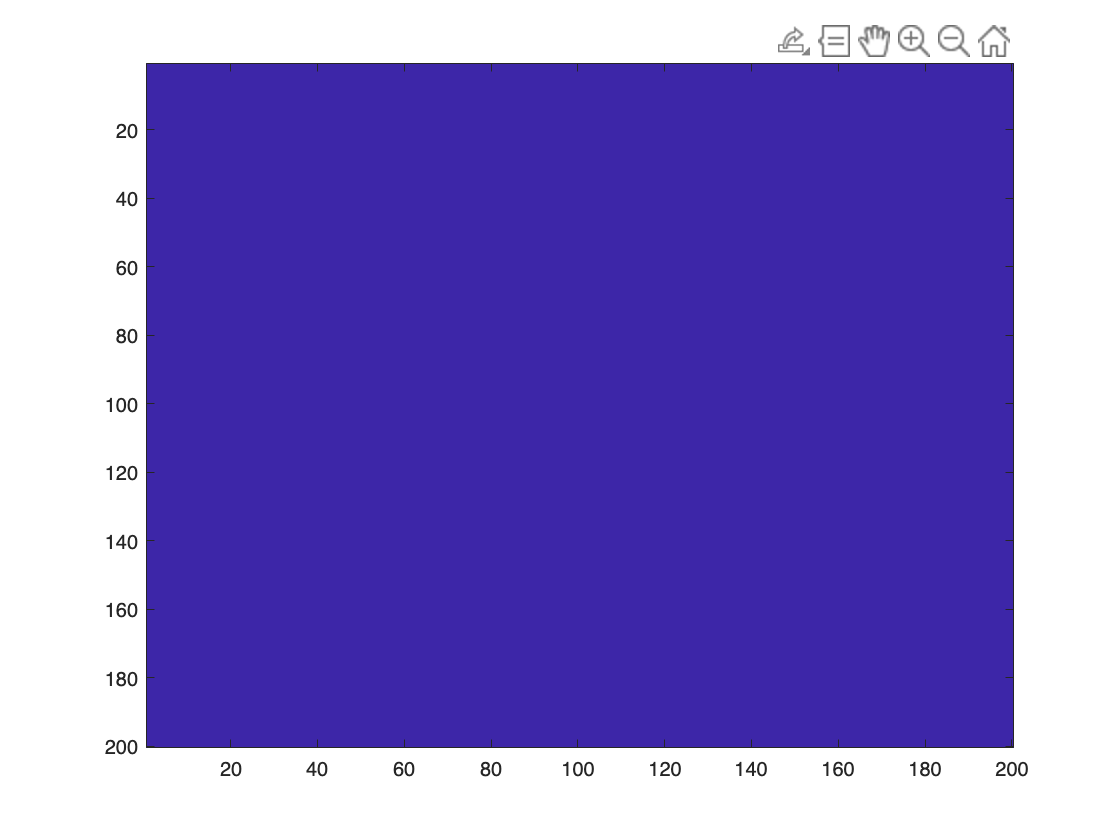

A = im2bw((squeeze(I(:,:,50))),.75); %Attempting to threshold, not sure the exact format I need for this problem. 
image(A)